T1list = dir('D:\KDD\2nd Semester\Dissertation\Datasets\Ideal_Spectral_Imgs\T1')

T1list = 34×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


path = fullfile(getfield(T1list,{1,1}, 'folder'));
T0savepath = 'D:\KDD\2nd Semester\Dissertation\Datasets\Ideal_Spectral_SIFT_Imgs\T1'

T0savepath = 'D:\KDD\2nd Semester\Dissertation\Datasets\Ideal_Spectral_SIFT_Imgs\T1'

%I = imread('D:\KDD\2nd Semester\Dissertation\Datasets\Ideal_Spectral_Imgs\T1\IMG_113.tiff');
%imshow(I)

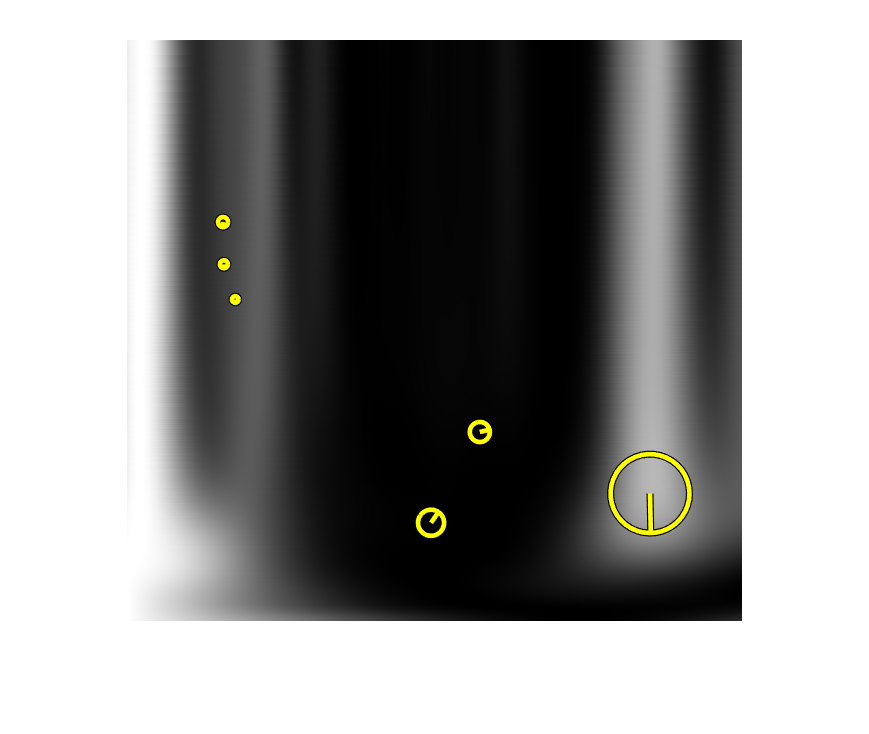

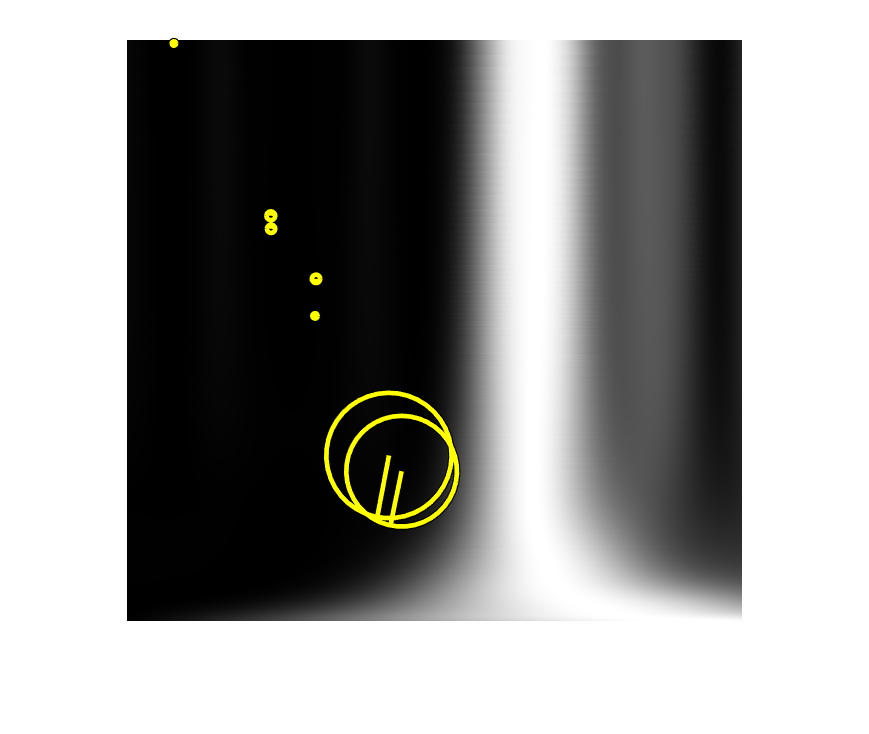

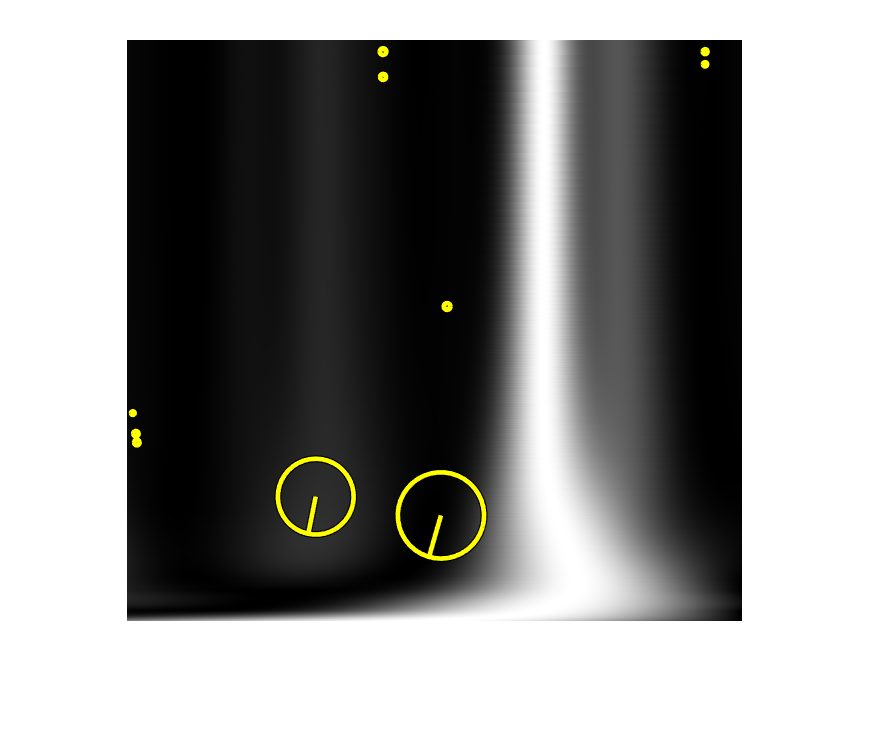

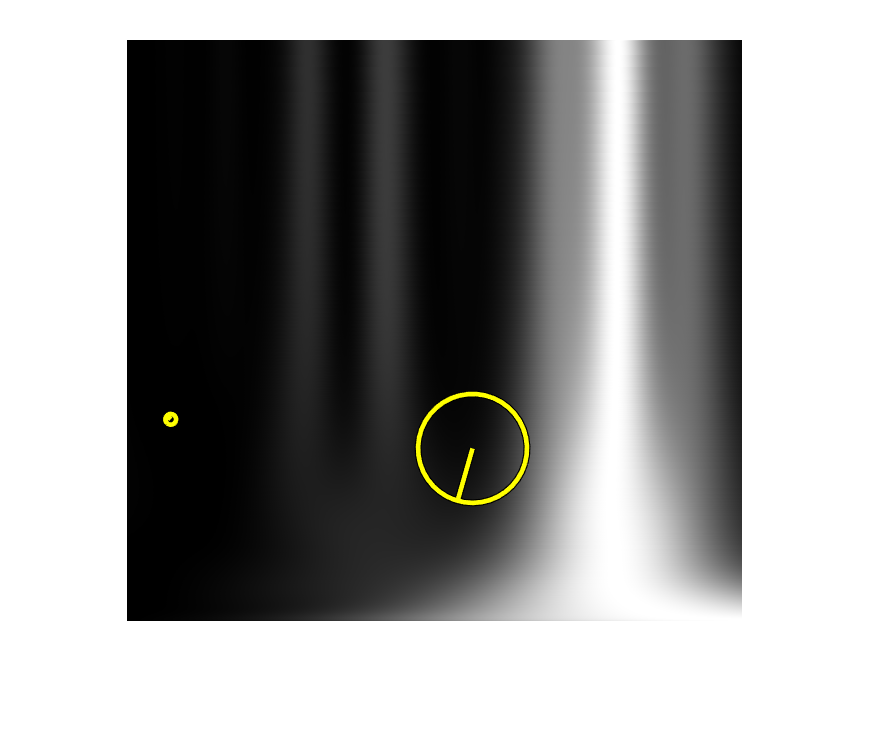

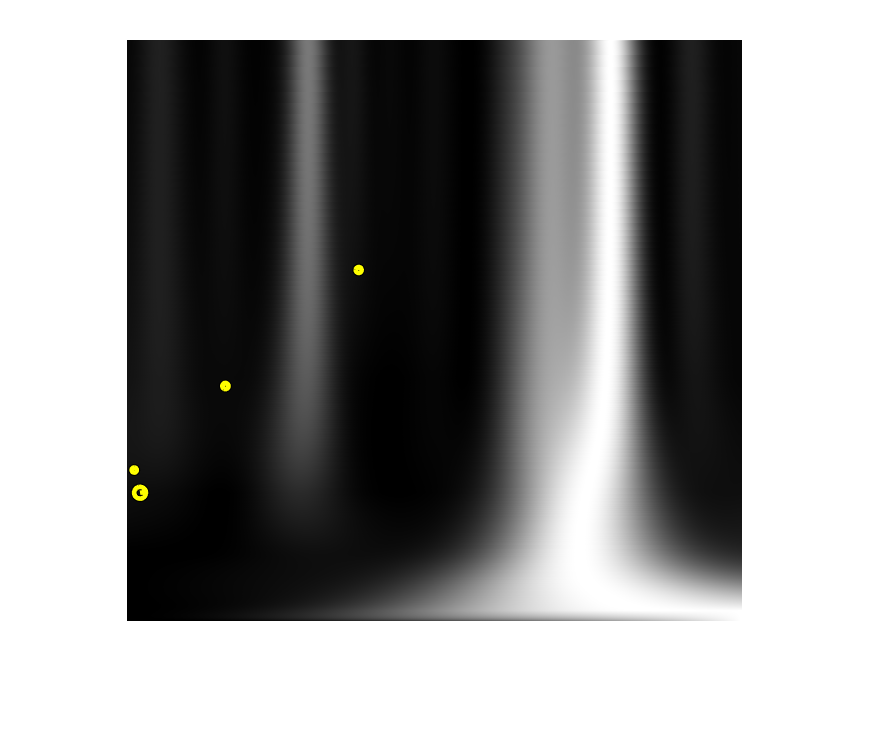

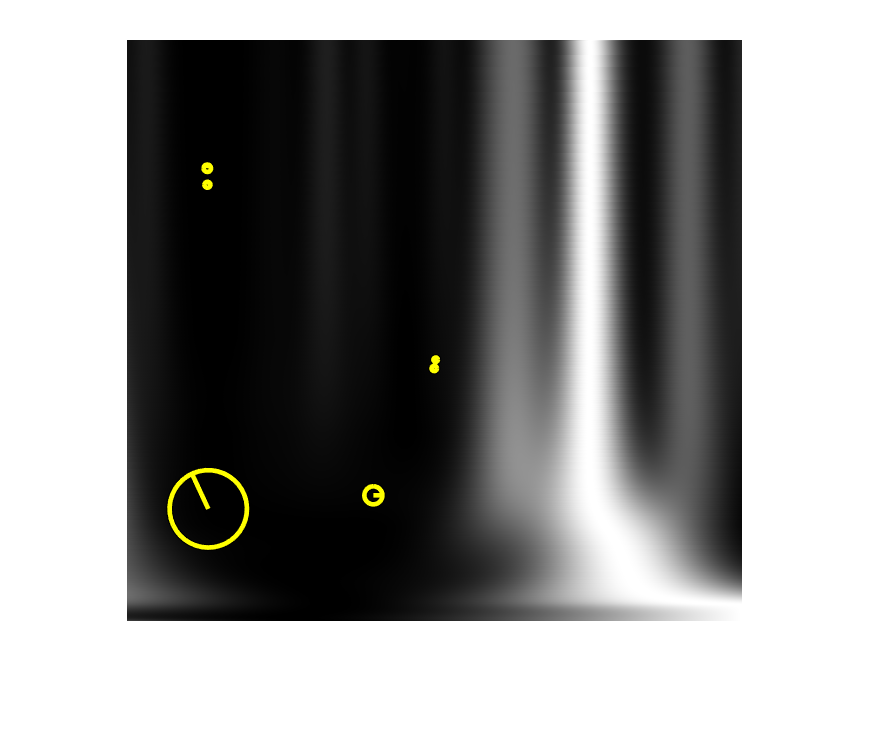

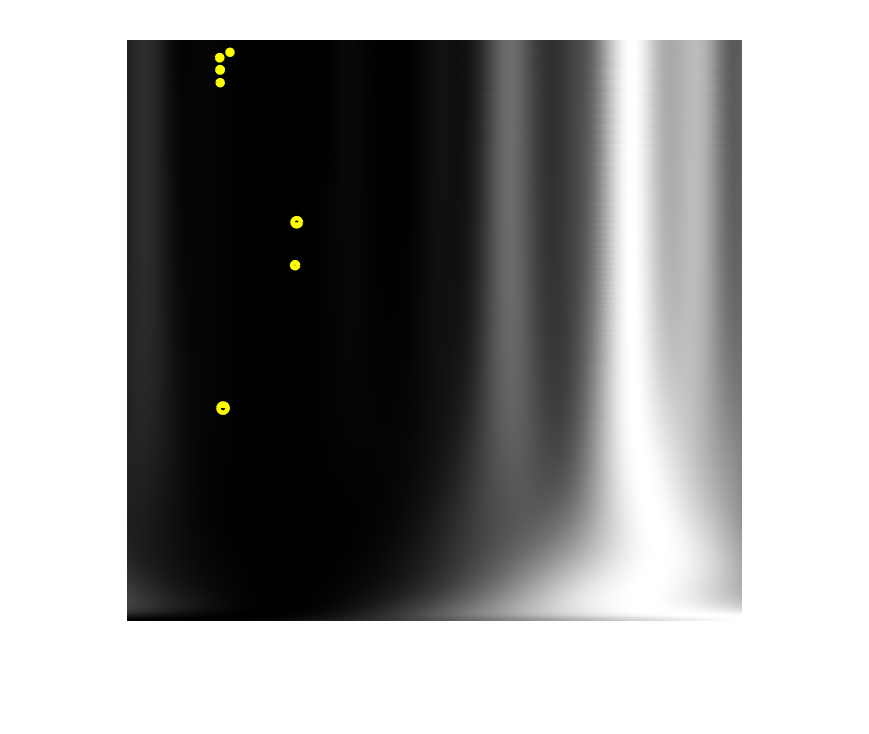

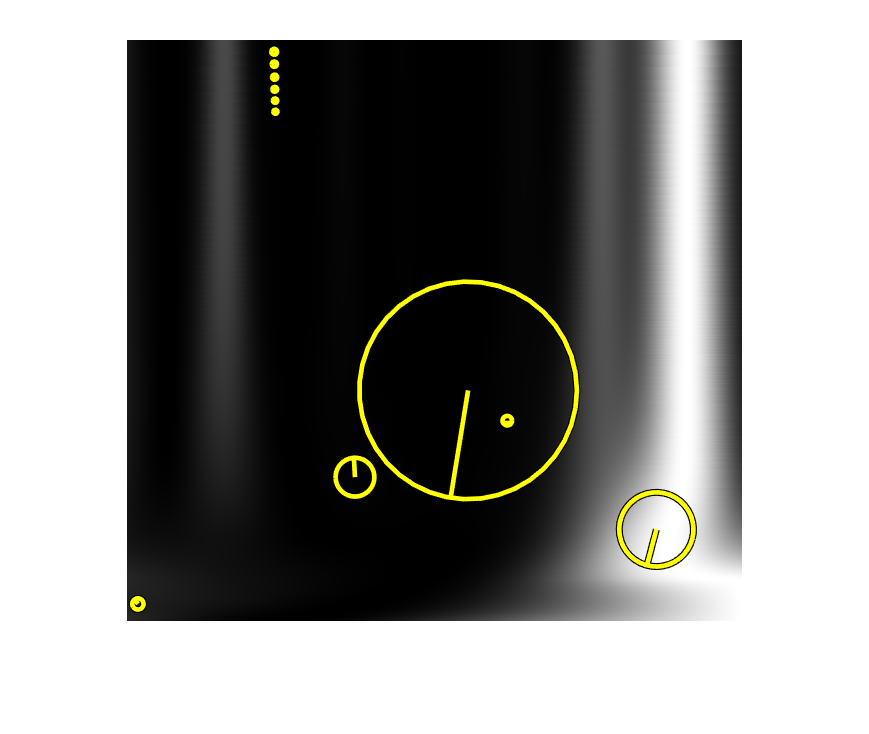

for i = 3:34
    img = fullfile(getfield(T1list,{i,1}, 'name'));
    I = imread(strcat(path,'\',img));
    [f,d] = vl_sift(I) ;
    figure
    imshow(I)
    hold on;

    %perm = randperm(size(f,2)) ;
    %sel = perm(1:50) ;
    %sel = perm;
    h1 = vl_plotframe(f) ;
    h2 = vl_plotframe(f) ;
    set(h1,'color','k','linewidth',3) ;
    set(h2,'color','y','linewidth',2) ;
    saveas(gcf,strcat(T0savepath,'\','IMG_',string(i),'.tiff'))
end        